TT=2000;
dt = 0.001;
t=0.001:dt:TT*dt;

VS = zeros(1, TT);
I =    zeros(1, TT);
FWE = zeros(1, TT);
TED = zeros(1, TT); 
ES = zeros (1, TT);
omega = zeros(1, TT);

Inertia = 137;
N=16;
L_HSX = 20e-3;
R_HSX = 90e-3;
RPM(1) = 1600;
kt=0;
k=0.6;
VS(1) = k*RPM(1);

FWE(1) = N*0.5*Inertia*(pi*RPM(1)/30)^2;

for i = 1:1:TT
    
    if i == 1
        I(i) = 0
    else
        dI = (VS(i-1) - I(i-1)*R_HSX)*dt/L_HSX;
        I(i) = I(i-1)+ dI;
    end
    
    if i == 1
        TED(i) = I(i)^2*R_HSX;
    else
        TED(i) = TED(i-1)+I(i)^2*R_HSX*dt;
    end
      
    ES(i) = 1/2*(I(i))^2*dt;
    
    NFE(i) = FWE(1) - TED(i) - ES(i);
    
    k_arr(i)=k;
    
    if i == 1
       NFE(i) = FWE(1);
       omega(i) = sqrt(NFE(i)/(N*0.5*Inertia));
    else
        NFE(i) = FWE(1) - TED(i) - ES(i);
        omega(i) = sqrt(NFE(i)/(N*0.5*Inertia));
        RPM(i) = 30*omega(i)/pi;
        
        
        if i > 100 && i < 885;
            kp=0.000000001;
            ki=0.000000001;
            kt=kt+1;
            error = 13600 - I(i);
            k=k+error*kp + error*ki*kt;
            k_arr(i)=k;
                    
        elseif k > 885;
             k_arr(i)=k;
        end
 
        
        VS(i) = RPM(i)*k;
      
    end
  
    
end

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


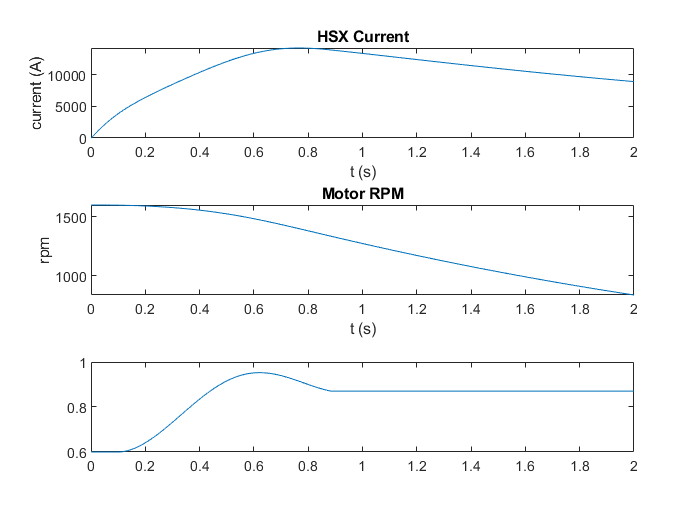


subplot(3,1,1)
plot(t, I)
title('HSX Current')
xlabel('t (s)')
ylabel('current (A)')
subplot(3,1,2)
plot(t, RPM)
title('Motor RPM')
xlabel('t (s)')
ylabel('rpm')
subplot(3,1,3)
plot(t, k_arr)